# Schätzen und Optimieren

## Aufgabe 1: 

Eine Software-Firma verwendet eine spezielle Methode um den Aufwand für eine Software zu schätzen. Dabei werden die Anforderungen analysiert und es wird eine Zahl ermittelt, welche den Aufwand beziffern soll (**Function-Points**).  Für die letzten 20 Projekte liegen diese Schätzungen vor: Zudem haben Sie die Abrechnungen mit den tatsächlich benötigten Aufwänden.

### **Functoin-Points** der letzten 20 Projekte:

        198 105 227 240 202 214 211 159 198 126 206 105 142 107 115 224 204 148 243 105

### Abgerechnter Aufwand der letzten 20 Projekte in Stunden:

        2432 1272 2714 3162 2636 2673 2511 1919 2442 1655 2445 1154 1668 1391 1491 2804 2518 1871 2958 1409

Für ein neues Projekt müssen Sie eine Offerte schreiben. Aus ihrer Anforderungsanalyse haben Sie für dieses Projekt  **180** Function-Points geschätzt. 

- Begründen Sie anhand eines scatter-Plots (scatter), ob diese Function-Point Zahl einen Anhaltspunkt für den tatsächlichen Aufwand liefern wird.

- Für wieviele Stunden offerieren Sie das Projekt?

- Zeichnen Sie ihr Modell, welches sie für diese Offerte verwendet haben, im scatter-Plot ein.

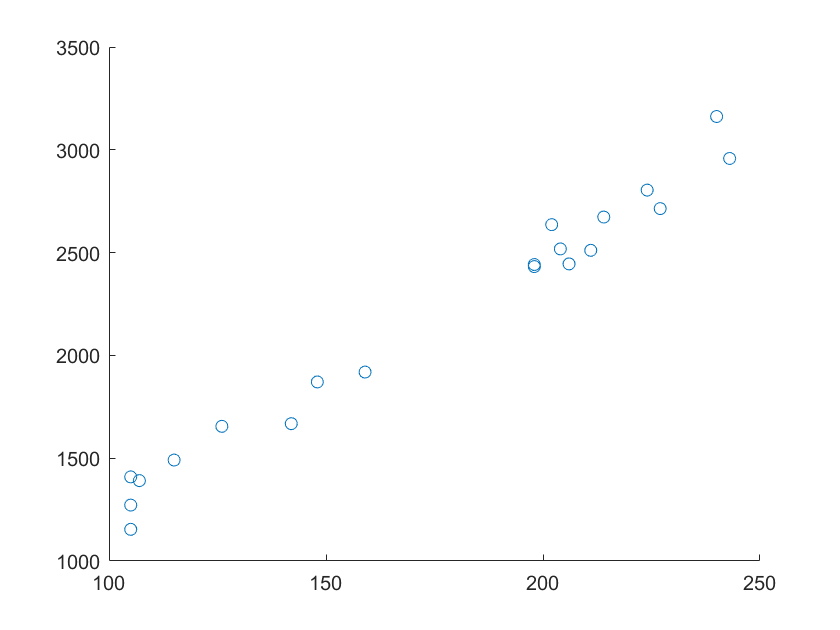

funpoints = [198 105 227 240 202 214 211 159 198 126 206 105 142 107 115 224 204 148 243 105];
effort = [2432 1272 2714 3162 2636 2673 2511 1919 2442 1655 2445 1154 1668 1391 1491 2804 2518 1871 2958 1409];

scatter(funpoints, effort);

%% Der Scatter-Plot zeigt eine deutliche korrelation zwischen effort und functionpoints
%% Auch logisch gesehen scheint es plausibel, dass diese Korrellation nicht rein zufällig zustandegekommen ist.

effortModel = fitlm(funpoints, effort)

effortModel = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)      15.97      76.341    0.20919       0.83665
    x1              12.304     0.42252      29.12    1.3557e-16


Number of observations: 20, Error degrees of freedom: 18
Root Mean Squared Error: 92.3
R-squared: 0.979,  Adjusted R-Squared: 0.978
F-statistic vs. constant model: 848, p-value = 1.36e-16

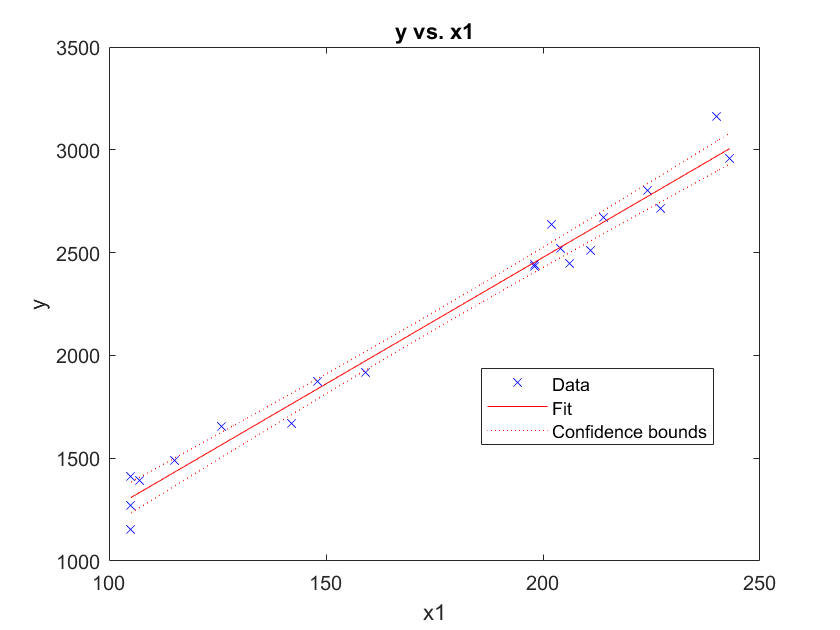


%% wenn wir das Modell plotten wird alle Punkte und das gefittete Modell gezeichnet
plot(effortModel);


%% parameter der Schätzung
slope = effortModel.Coefficients.Estimate(2);
intercept = effortModel.Coefficients.Estimate(1);

%% obwohl der parameter intercept nicht signifikant von 0 verschieden ist, würde
%% ich ihn bei der Offerte berücksichtigen. Wir wollen ja nicht "draufzahlen"
%% es würde wohl sogar sinn machen ein bisschen mehr aufzurunden!
OFFERTE = slope*180 + intercept; % = 2307

%% Ich würde die Offerte bei ca 2350.- ansetzen.

## Aufgabe 2:

Eine Würstchenbude verkauft pro Monat 1000 Würstchen mit Brot. Gesamthaft wird ca. 210 Kg Bort verbraucht. Die Bude hat zwei Lieferanten. 

Liferant 1 liefert Brot zu 5.0.-Fr. pro Kg und Würste zu 2.5 Fr. pro Wurst.  Die Würste werden in 50-er Packungen verkauft und pro Wurstpackung müssen 20 Kg Brot gekauft werden.

Lieferant 2 liefert Würstchen zu 3.0 Fr. und Brot zu 4.0 Fr. pro Kg. Es besteht ein Liefervertrag, mit einer garantierten Abnahmemenge von 200 Würsten und 20 Kg Brot.

- Wie soll die Bestellung aussehen, um die Kosten zu minimieren und den Bedarf zu decken? Wieviele Würste und wieviel Kg Brot wird bei welchem Liferanten bestellt?

**Antwort: **

**Das vorgeschlagene Modell ist korrekt. Wir müssen also nur die Lösung richtig interpretieren.**

**Bei Liferant 1 werden 9 Bestell-Einheiten eingekauft.**

**Bei Liferant 1 werden  = 9*20Kg = 180 Kg Brot bestellt.**

**Bei Liferant 1 werden  = 9*50 = 450 Würste bestellt.**

**Bei Liferant 2 werden 30 Kg Brot bestellt.**

**Bei Liferant 2 werden 550 Würste bestellt.**

m1 = optimvar("bestellmengeL1", "Type","integer", "LowerBound",0);

b2 = optimvar("brot2", "Type","integer", "LowerBound",20);

w2 = optimvar("wurst2", "Type","integer", "LowerBound",200);

bestellung = optimproblem("ObjectiveSense","minimize");
bestellung.Objective = m1* 20 * 5.0 + m1*50 *2.5 + b2*4.0 + w2*3.0;
bestellung.Constraints.Brot = m1*20 + b2 >= 210;
bestellung.Constraints.Wurst = m1*50 + w2 >= 1000;

[solution, cost] = solve(bestellung);

Solving problem using intlinprog.
LP:                Optimal objective value is 3792.500000.                                          

Heuristics:        Found 1 solution using ZI round.                                                 
                   Upper bound is 3905.000000.                                                      
                   Relative gap is 2.82%.                                                          

Cut Generation:    Applied 1 mir cut.                                                               
                   Lower bound is 3795.000000.                                                      
                   Relative gap is 0.00%.                                                          


Optimal solution found.

Intlinprog stopped at the root node because the objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default v

## Aufgabe 3:

Eine Unternehmung hat drei Werbe-Kanäle mit unterschiedlichen Kosten und unterschiedlicher Wirkung auf die verschiedenen Kundensegmente.

Die Kundensegmente sind

- KS1: Jugendliche und junge Erwachsene

- KS2: Erwachsene

- KS3: Senioren

- Kanal1: Inserate in einem Internet-Portal: Kosten 500.- pro Woche

- Kanal2: Direkt Mailing: Kosten 200.- pro Mailing Kampagne. Sie können maximal 1 Mailing-Kampagne pro Woche durchführen.

- Kanal3: Inserat in einer Zeitschrift: Kosten 1000.- pro Inserat

 Der Werbeeffeckt wird in einer Zahl (**WE**) gemessen und beschrieben. Diese Zahl drückt aus, wieviel Mehrumsatz diese Kunden in Zukunft  generieren werden. 

- Wirkung Kanal 1: KS1 = 30 , KS2 = 5, KS3 = 0 

- Wirkung Kanal 2: KS1 = 0, KS2 = 15, KS3 = 2

- Wirkund Kanal 3: KS1 = 5, KS2 = 7, KS3 = 10

Damit Sie keine Kunden verlieren, müssen Sie beim Kundensegment KS1 mindestens einen Werbeeffekt von 100 beim Kundensegment KS2 einen Werbeeffekt von 150 und bei den Senioren einen Werbeeffekt von 80 erzielen.

Sie haben ein Werbebudget von 15000.- Pro Jahr. 

- Auf welchen Kanälen werben Sie, um den Werbeeffekt zu maximieren und keine Kunden zu verlieren. 

- Wieviel Werbeeffekt Punkte werden Sie erzielen?

**Antwort: **

**Das Modell ist logisch korrekt. Die Koeffizienten in der Gleichung effectSen und die Kosten im Budget.Constraint für die Mailings stimmen aber nicht und müssen gemäss Aufgabenstellung angepasst werden.**

**Mit diesen Nebenbedinungen wird nur mit Mailings und Zeitschriften geworben.**

**=> 0 Inserate**

**=> 50 Mailings**

**=> 10 Zeitschriften**

**=> Werbeeffect = 1200 Punkte**

x1 = optimvar("portal", "Type","integer","LowerBound", 0);
x2 = optimvar("mailings", "Type", "integer", "LowerBound", 0, "UpperBound",52);
x3 = optimvar("inserate", "Type","integer", "LowerBound", 0);

effectYoung = x1 * 30 + x3 * 5;
effectAdult = x1 * 5 +  x2 *15 + x3 * 7;
effectSen = x2 *2 + x3 * 10; 

werbung = optimproblem("ObjectiveSense","maximize");
werbung.Objective = effectYoung + effectAdult + effectSen;
werbung.Constraints.Budget = x1*500 + x2*200 + x3*1000 <= 15000;
werbung.Constraints.DontLooseYoung = effectYoung >= 100;
werbung.Constraints.DontLooseAdult = effectAdult >= 150;
werbung.Constraints.DontLooseSen = effectSen >= 80;

[sol, e] = solve(werbung);

Solving problem using intlinprog.
LP:                Optimal objective value is -1206.000000.                                         

Heuristics:        Found 1 solution using ZI round.                                                 
                   Upper bound is -1199.000000.                                                     
                   Relative gap is 0.08%.                                                          

Cut Generation:    Applied 1 Gomory cut.                                                            
                   Lower bound is -1200.000000.                                                     
                   Relative gap is 0.00%.                                                          


Optimal solution found.

Intlinprog stopped at the root node because the objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default v

## Aufgabe 4

Dieselbe Unternehmung wie in Aufgabe 3 stellt fest, dass Sie Kunden im Senioren-Segment (KS3) verlieren. Und das, obwohl die Werbe-Kanäle so gewählt wurden, dass das nicht hätte passiern dürfen. 

Es wird eine Studie in Auftrag gegeben, um die Werbewirksamkeit der Inserate bei Senioren zu untersuchen. Die Beauftragte Firma stellt Ihnen diese Zahlen vor.

Anzahl Inserate: 

8     9     1     9     6     1     3     5    10    10

Werbe-Effekte:

63    54    -2    57    18    19    24    29    81    56

Berechnen Sie anhand dieser Zahlen eine Schätzung der Werbewirksamkeit. 

- Kann diese neue Schätzung eine Erklärung für das Problem liefern? Begründung.

- Rechnen Sie das Optimierungsproblem aus Aufgabe 3 mit der neuen Schätzung. Wie gross ist der gesamte Werbeeffekt jetzt?

**Antwort:**

**Nein, der Werbeeffect wurde überschätzt. Trotz dieser Überschätzung wurden gar keine Inserate eingesetzt. Wenn der Werbeeffekt noch kleiner wird, wird sich das Werben mit Inseraten noch weniger lohnen! Man muss also die anderen Parameter des Modells auch überprüfen.**

**Inserate 0, Mailings 50 und Zeitschriften 10**

**Gesamt Werbeeffekt Punkte = 1200**

inserate = [8 9 1 9 6 1 3 5 10 10];
effektInserate = [63 54 -2 57 18 19 24 29 81 56];

effectModel = fitlm(inserate, effektInserate)

effectModel = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat        pValue  
                   ________    ______    _________    __________

    (Intercept)    -0.55282     8.044    -0.068724        0.9469
    x1               6.5246    1.1399        5.724    0.00044201


Number of observations: 10, Error degrees of freedom: 8
Root Mean Squared Error: 12.1
R-squared: 0.804,  Adjusted R-Squared: 0.779
F-statistic vs. constant model: 32.8, p-value = 0.000442

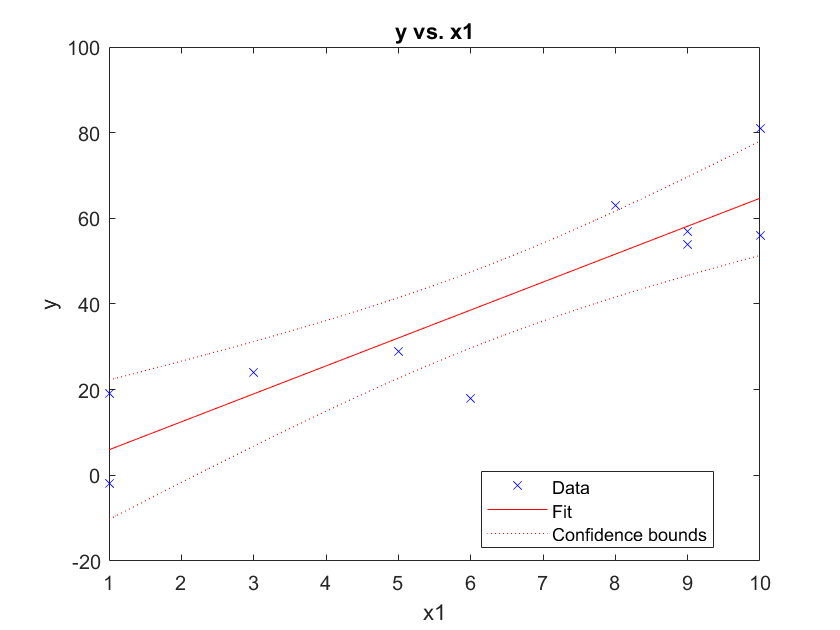

plot(effectModel);

%% Der geschätzte Werbeeffect mit diesen Zahlen beträgt 6.5
%% Das ist zwar tatsächlich anders als was zuvor geschätzt wurde. Es wird aber keinen Einfluss haben, da gar nie mit Inseraten geworben wurde!

x12 = optimvar("portal", "Type","integer","LowerBound", 0);
x22 = optimvar("mailings", "Type", "integer", "LowerBound", 0, "UpperBound",52);
x32 = optimvar("inserate", "Type","integer", "LowerBound", 0);

effectYoung2 = x12 * 30 + x32 * 5;
effectAdult2 = x12 * 5 +  x22 *15 + x32 * 7;
effectSen2 = x22 *2 + x32 * 6.5; %% das ist der neu berechnete Wert; hat aber keinen Einfluss!;

werbung2 = optimproblem("ObjectiveSense","maximize");
werbung2.Objective = effectYoung2 + effectAdult2 + effectSen2;
werbung2.Constraints.Budget = x12*500 + x22*200 + x32*1000 <= 15000;
werbung2.Constraints.DontLooseYoung = effectYoung2 >= 100;
werbung2.Constraints.DontLooseAdult = effectAdult2 >= 150;
werbung2.Constraints.DontLooseSen = effectSen2 >= 80;

[sol2, e2] = solve(werbung2);

Solving problem using intlinprog.
LP:                Optimal objective value is -1206.000000.                                         

Heuristics:        Found 1 solution using ZI round.                                                 
                   Upper bound is -1199.000000.                                                     
                   Relative gap is 0.08%.                                                          

Cut Generation:    Applied 1 Gomory cut.                                                            
                   Lower bound is -1200.000000.                                                     
                   Relative gap is 0.00%.                                                          


Optimal solution found.

Intlinprog stopped at the root node because the objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default v